# Simulating a Simple Pendulum

[Open live script](matlab:edit pendulumExample)

This example shows how to create a 3D model of a simple pendulum.

The equations of motion of a simple pendulum are


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}\theta =\omega ,\\
\frac{\mathrm{d}}{\mathrm{d}t}\omega =-\text{ }\frac{g}{L}\text{ }\theta ={-\text{ }\omega }_0^2 \text{ }\theta \text{ },
\end{array}$$


where 

- $\theta$ is the rod's angular position measured from the vertical equilibrium, 

- $\omega$ is its angular velocity, 

- $g$ is the acceleration due to gravity, 

- $L$ is the rod's length, and 

- $\omega_0$ is its natural frequency. 

The discrete form of the equations of motion are


$$\begin{array}{l}
\theta \left(t+\text{dt}\right)=\theta \left(t\right)+\omega \left(t\right)\text{ }\text{dt},\\
\omega \left(t+\text{dt}\right)=\omega \left(t\right)-\omega_0^2 \text{ }\theta \left(t+\text{dt}\right)\text{ }\text{dt}\ldotp 
\end{array}$$


Define the physical parameters.

L = 1;    % length of the rod (meters)
g = 9.81; % acceleration due to gravity (kg m s^-2)
omega_0 = sqrt(g/L); % natural frequency
t_0 = 2*pi/omega_0;  % period

Build the pendulum.

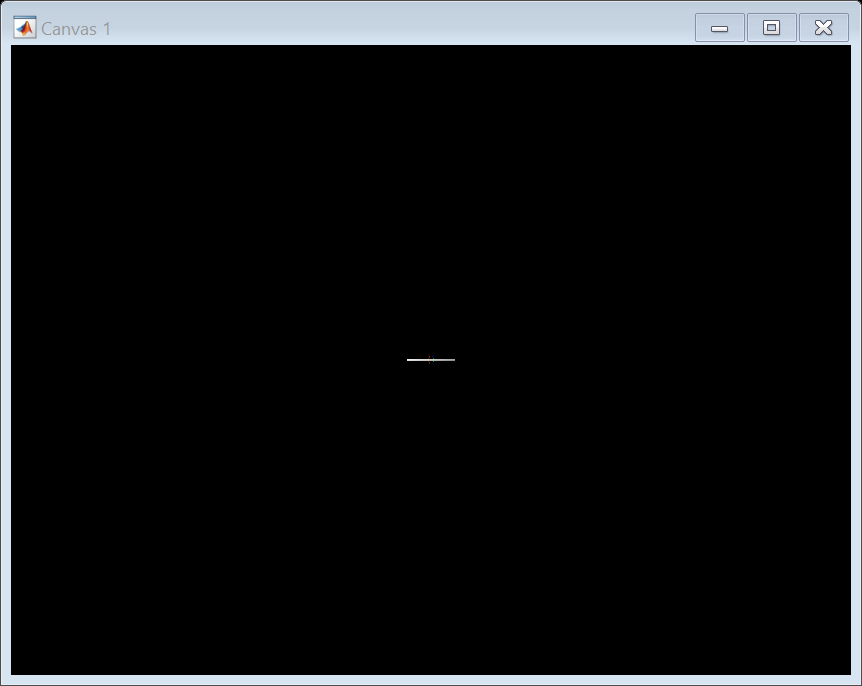

baseThickness = 0.05*L;
baseWidth = L;
base = physvis.Box('Size',[baseWidth baseThickness baseWidth]);

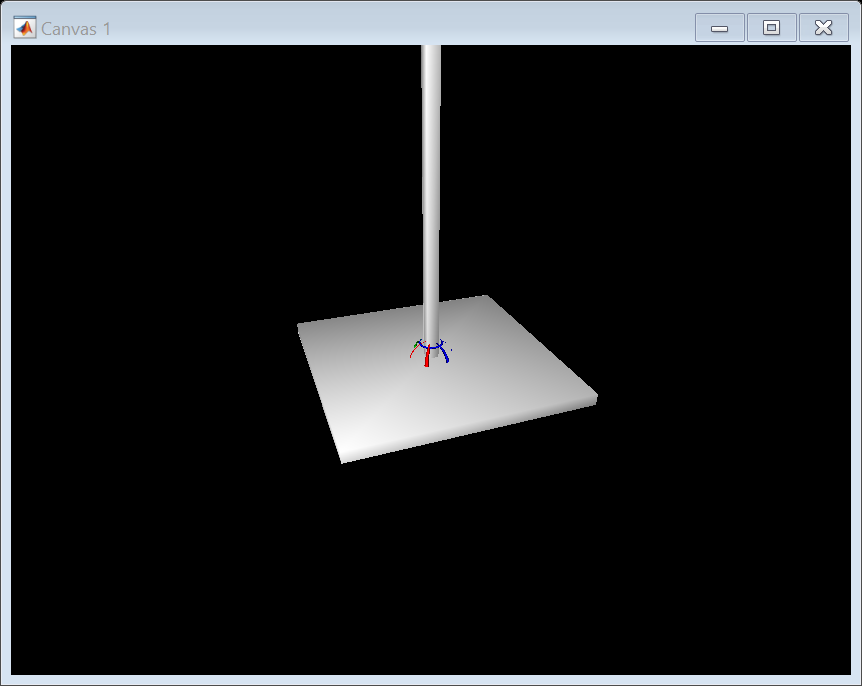

standHeight = 1.25*L;
standThickness = baseThickness;
stand = physvis.Box('Size',[standThickness standHeight standThickness]);
stand.Position(2) = standHeight/2;

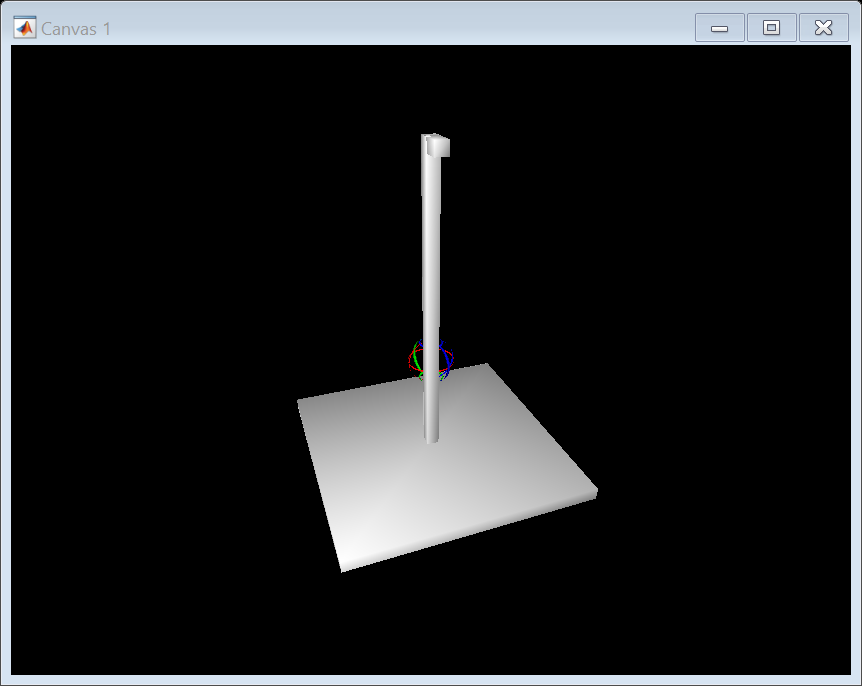

pivotLength = 2*standThickness;
pivotThickness = standThickness;
pivot = physvis.Box('Size',[pivotThickness pivotThickness pivotLength]);
pivot.Position = [0, standHeight-pivotThickness/2, pivotLength/2];

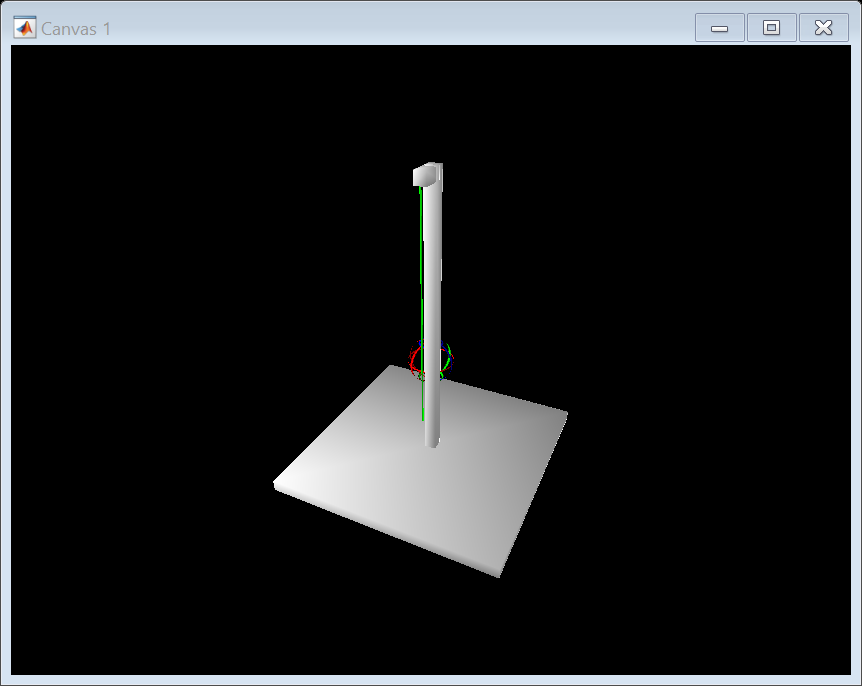

rodThickness = 0.1*standThickness;
rod = physvis.Box('Size',[rodThickness L rodThickness],'Color','green');
rod.Position = [0, standHeight-pivotThickness/2-L/2, pivotLength-rodThickness];

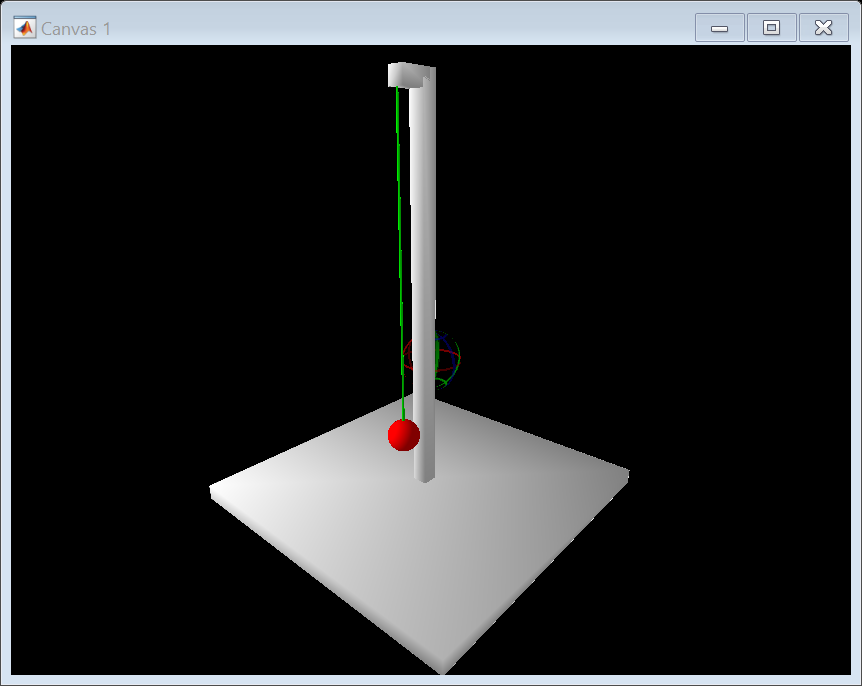

R = 0.05*L;
bob = physvis.Sphere('Radius',R,'Color','red');
bob.Position = rod.Position - L/2*[0 1 0];
bob.HasTrail = true;
bob.Retain = 20;
bob.TrailType = 'curve';

Set initial conditions.

dt = 2^-6;

t = 0;
theta = pi/8;
omega = 0;

Rotate(rod, theta, [0 0 1], pivot.Position);
Rotate(bob, theta, [0 0 1], pivot.Position);

Evolve the system

while isvalid(bob.Canvas)
    theta = theta + omega * dt;
    omega = omega - omega_0^2 * theta * dt;
   
    Rotate(rod, omega * dt, [0 0 1], pivot.Position);
    Rotate(bob, omega * dt, [0 0 1], pivot.Position);    
    
    rate(1/dt);
    t = t + dt;
end